close all
clear variables

spectra = importdata('spectra.csv');
lambdaStart = importdata('lambda_start.csv');
lambdaDelta = importdata('lambda_delta.csv');
starNames = importdata('star_names.csv');

lambdaPr = 656.28; %нм
speedOfLight = 299792.458; %км/с

nObs = size(spectra, 1);
lambdaEnd = lambdaStart + (nObs - 1) * lambdaDelta;
lambda = (lambdaStart : lambdaDelta : lambdaEnd)';

nObss = size(spectra, 2);
speed = 1:1:nObss;

i = 1;

while i < nObss + 1
    s = spectra(:, i);
    [sHa, idx] = min(s);
    hlambdaHa = lambda(idx);

    z = (hlambdaHa / lambdaPr) - 1;
    speed(i) = z * speedOfLight;

    i = i + 1;
end

St = 1:1:nObss;
movaway = starNames(St (speed' > 0))

movaway = 3×1 cell array
    {'HD5211' }
    {'HD56030'}
    {'HD94028'}


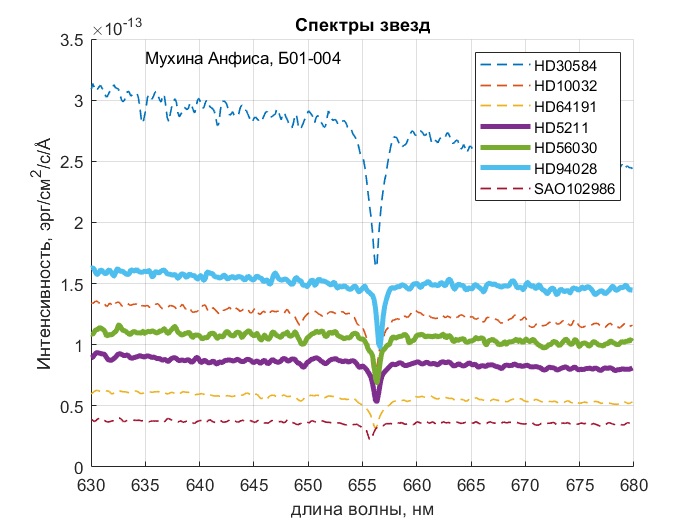


fg1 = figure;
hold on

for n = 1:1:nObss
    
    if speed(n) < 0
        plot (lambda, spectra(:, n), "--", "LineWidth", 1)
    else
        plot (lambda, spectra(:, n), "LineWidth", 3)
    end
    
end

set(fg1, 'visible', 'on')
xlabel('длина волны, нм')
ylabel(['Интенсивность, эрг/см^2/с/', char(197)])
title ('Спектры звезд')
text (635, 3.35*10^-13, 'Мухина Анфиса, Б01-004');
legend (starNames)
grid on
hold off

saveas (fg1, 'spectr.png')